# **unsteady-state Flux Balance Analysis (FBA)**

## **James T. Yurkovich**

In this tutorial, we will use unsteady-state Flux Balance Analysis (uFBA) [1] to integrate exo- and endo-metabolomics data [2] into a constraint-based metabolic model for the human red blood cell [3]. Running this method requires the installation of a mixed-integer linear programming solver; we have used Gurobi 7.0.0 (http://www.gurobi.com/downloads/download-center) which is freely available for academic use. 

## Preliminaries

We can model the flux through a metabolic network using a set of linear equations defined by


$$\mathbf{S}\cdot \mathbf{v}=\mathbf{b}$$


where **S** is the stoichiometric matrix, **v** is a vector of fluxes through the chemical reactions defined in **S**, and **b** represents constraints on metabolite concentrations; at steady-state, **b **= 0. The first step of the uFBA workflow is to identify discrete time intervals which represent linearized metabolic states (Fig. 1). For each metabolic state, we can use linear regression to calculate the rate of change of each metabolite concentration. If the rate of change is significant, the model is updated by changing the steady-state constraint from 0 to 


$$\begin{array}{l}
\mathbf{S}\cdot \mathbf{v}\text{ }\ge {\mathbf{b}}_1 \\
\mathbf{S}\cdot \mathbf{v}\text{ }\le {\mathbf{b}}_2 
\end{array}$$


where [$\mathbf{b}_1$, $\mathbf{b}_2$] represents the 95% confidence interval for each significantly changing metabolite. All unmeasured metabolites are assumed to be at steady-state (i.e., $\mathbf{b}_1 = \mathbf{b}_2 = 0$).

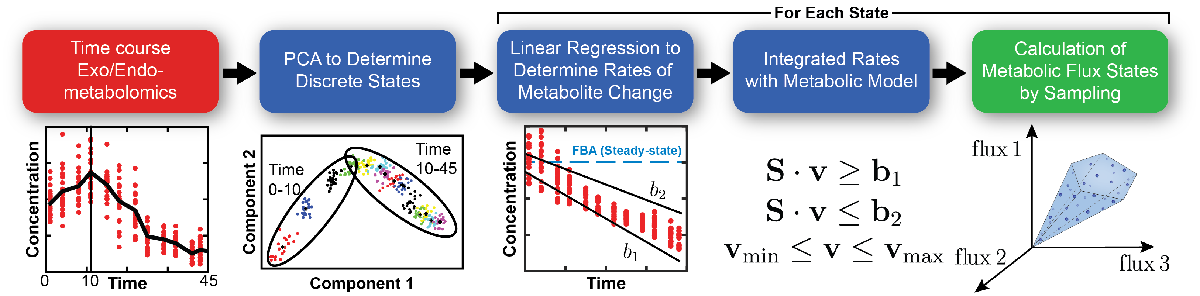

                                                    Fig. 1 | Overview of the uFBA workflow.

## Example 

initCobraToolbox()

We first load in the data. This data is absolutely quantified and has already been volume adjusted such that intracellular and extracellular metabolite concentrations have compatible units. 

load sample_data;

changeCobraSolver('gurobi7', 'LP');
changeCobraSolver('gurobi7', 'MILP');

The `sample_data.mat` file contains the following variabels:

- `met_data`: a matrix containing the exo- and endo-metabolomics data

- `met_IDs`: a cell array containing the BiGG ID for each of the metabolites in `met_data`

- `model`: a modified version [3] of the iAB-RBC-283 COBRA model structure

- `time`: a vector of the time points (in days) at which the metabolite concentrations were measured

- `uFBAvariables`: a struct containing the variables necessary for input into the uFBA algorithm

Next, we run linear regression to find the rate of change for each metabolite concentration.

changeSlopes = zeros(length(met_IDs), 1);
changeIntervals = zeros(length(met_IDs), 1);
for i = 1:length(met_IDs)
    [tmp1, tmp2] = regress(met_data(:, i), [time ones(length(time), 1)], 0.05);
    changeSlopes(i, 1) = tmp1(1);
    changeIntervals(i, 1) = abs(changeSlopes(i, 1) - tmp2(1));
end

The variables `changeSlopes` and `changeIntervals` contain the metabolite rates of change and 95% confidence intervals, respectively. We will create a new vector, `ignoreSlopes`, which contains a `1` for the metabolites whose slopes change significantly and a `0` otherwise:

tmp1 = changeSlopes - changeIntervals;
tmp2 = changeSlopes + changeIntervals;
ignoreSlopes = double(tmp1 < 0 & tmp2 > 0);

Finally, we need to input the data into the uFBA algorithm which is encapsulated in the function `buildUFBAmodel`. This function takes as input a COBRA model structure and a struct containing the required input variables (see Table 1).

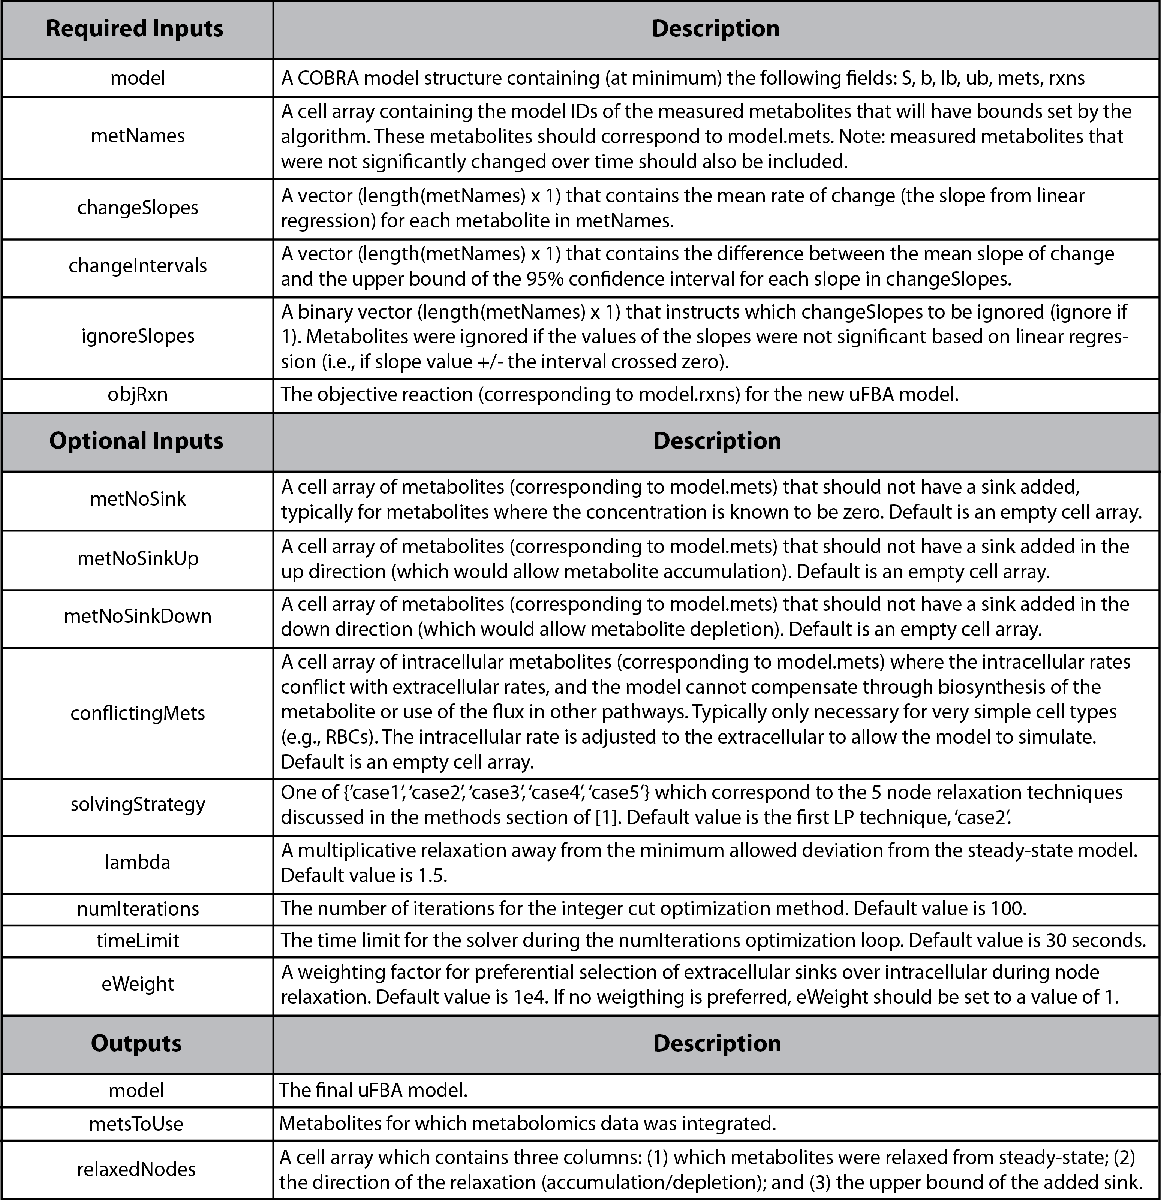

                                       Table 1 | Inputs and outputs of the `buildUFBAmodel` function.

uFBAvariables.metNames = met_IDs;
uFBAvariables.changeSlopes = changeSlopes;
uFBAvariables.changeIntervals = changeIntervals;
uFBAvariables.ignoreSlopes = ignoreSlopes;

uFBAoutput = buildUFBAmodel(model, uFBAvariables);

sink_ascb-L[c]	ascb-L[c] 	<=>	
sink_gthrd[e]	gthrd[e] 	<=>	
sink_urate[e]	urate[e] 	<=>	
sink_10fthf[c]_up	10fthf[c]_G + 10fthf[c]_L 	->	
sink_13dpg[c]_up	13dpg[c]_G + 13dpg[c]_L 	->	
sink_2kmb[c]_up	2kmb[c]_G + 2kmb[c]_L 	->	
sink_35cgmp[c]_up	35cgmp[c]_G + 35cgmp[c]_L 	->	
sink_35cgmp[e]_up	35cgmp[e]_G + 35cgmp[e]_L 	->	
sink_5mdr1p[c]_up	5mdr1p[c]_G + 5mdr1p[c]_L 	->	
sink_5mdru1p[c]_up	5mdru1p[c]_G + 5mdru1p[c]_L 	->	
sink_6pgl[c]_up	6pgl[c]_G + 6pgl[c]_L 	->	
sink_ac[c]_up	ac[c]_G + ac[c]_L 	->	
sink_accoa[c]_up	accoa[c]_G + accoa[c]_L 	->	
sink_adn[c]_up	adn[c]_G + adn[c]_L 	->	
sink_adn[e]_up	adn[e]_G + adn[e]_L 	->	
sink_akg[c]_up	akg[c]_G + akg[c]_L 	->	
sink_akg[e]_up	akg[e]_G + akg[e]_L 	->	
sink_ala-L[e]_up	ala-L[e]_G + ala-L[e]_L 	->	
sink_ametam[c]_up	ametam[c]_G + ametam[c]_L 	->	
sink_arg-L[e]_up	arg-L[e]_G + arg-L[e]_L 	->	
sink_asn-L[e]_up	asn-L[e]_G + asn-L[e]_L 	->	
sink_band[c]_up	band[c]_G + band[c]_L 	->	
sink_bandmt[c]_up	bandmt[c]_G + bandmt[c]_L 	->	
sink_ca2[

The resulting model (`uFBAoutput.model`) can be converted back to a steady-state COBRA model (i.e., $\mathbf{S \cdot v} = 0$) using the function `ufba2fba` so that standard COBRA methods can be used:

model_ufba = optimizeCbModel(uFBAoutput.model)

## References

[1] A Bordbar*, JT Yurkovich*, G Paglia, O Rolfsson, O Sigurjonsson, and BO Palsson. "Elucidating dynamic metabolic physiology through network integration of quantitative time-course metabolomics." *Scientific Reports *(2017). doi:10.1038/srep46249. (* denotes equal contribution)

[2] A Bordbar, PI Johansson, G Paglia, SJ Harrison, K Wichuk, M Magnusdottir, S Valgeirsdottir, M Gybel-Brask, SR Ostrowski, S Palsson, O Rolfsson, OE Sigurjonsson, MB Hansen, S Gudmundsson, and BO Palsson. "Identified metabolic signature for assessing red blood cell unit quality is associated with endothelial damage markers and clinical outcomes." *Transfusion* (2016). doi:10.1111/trf.13460.

[3] A Bordbar, D McCloskey, DC Zielinski, N Sonnenschein, N Jamshidi, and BO Palsson. "Personalized Whole-Cell Kinetic Models of Metabolism for Discovery in Genomics and Pharmacodynamics." *Cell Systems* (2015). doi:10.1016/j.cels.2015.10.003.